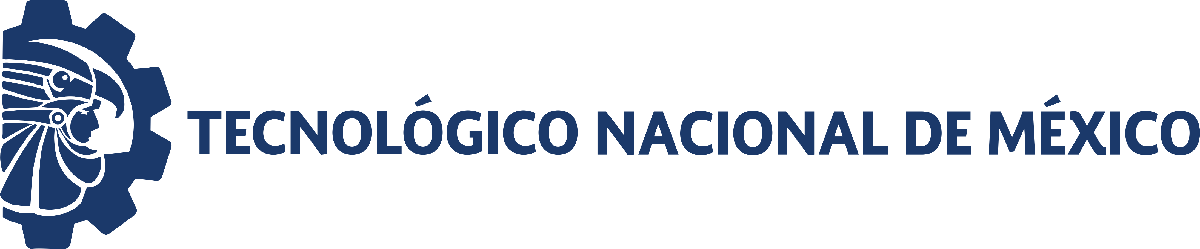                                 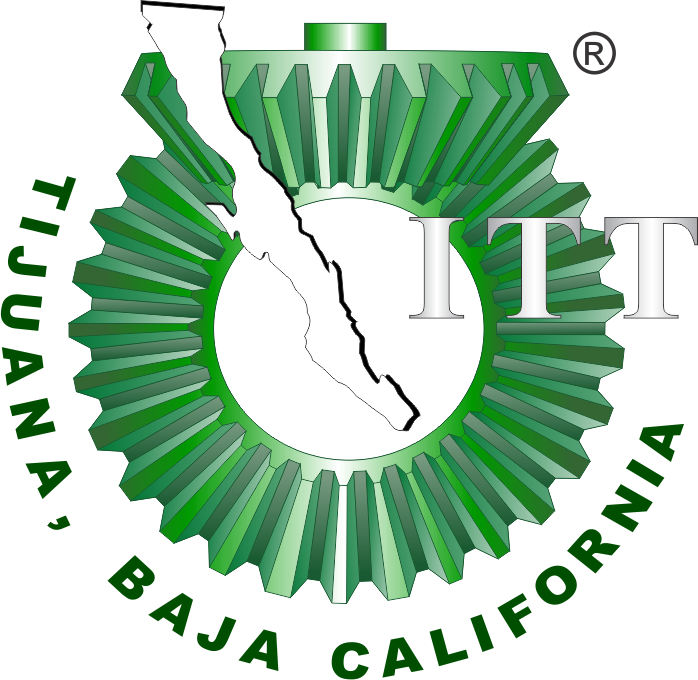

# Práctica 5: Regeneracion de globulos rojos

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general           

Nombre del alumno: LOPEZ LOPEZ SANTIAGO

Número de control: 22212260

Correo institucional: l22212260**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = 180; %Tiempo de simulacion en dias 
dt = 1E-3; %Intervalo de integracion para el metodo de solucion por diferencias finitas
n = round(tend/dt); %Cantidad de iteraciones para el metodo numerico

%Condiciones iniciales base para cada paciente
x1_0 = 59; x2_0 = 44; x3_0 = 855;

%Parametros particulares para cada paciente
gamma = [0.769;0.388; 0.510; 0.590; 0.262; 0.324; 0.356; 0.089; 0.243; 0.057];
beta = [1.650; 0.867; 1.617; 2.615; 1.518; 2.676; 0.891; 2.557; 0.925; 0.879];

seed = 22212260; %Semilla para asegurar reproducibilidad
rng(seed, 'twister')
%Intervalo de las condiciones iniciales 
xmin = 0.99; xmax = 1.01;
interval = xmin + (xmax-xmin).*rand(numel(gamma),1); 

%Condiciones iniciales para cada paciente
x1_0 = x1_0*interval; disp('x1(0) ='); disp(x1_0');...
x2_0 = x2_0*interval; disp('x2(0) ='); disp(x2_0');...
x3_0 = x3_0*interval; disp('x3(0) ='); disp(x3_0');

x1(0) =
   59.1299   59.0526   58.4867   59.5058   58.6505   59.3282   58.4418   58.5115   59.5468   59.5625



x2(0) =
   44.0969   44.0393   43.6172   44.3772   43.7394   44.2447   43.5837   43.6357   44.4078   44.4195



x3(0) =
  856.8823  855.7629  847.5616  862.3297  849.9352  859.7556  846.9105  847.9213  862.9241  863.1518



## Caso: Sin transfusion sanguinea [u(t)=0] 

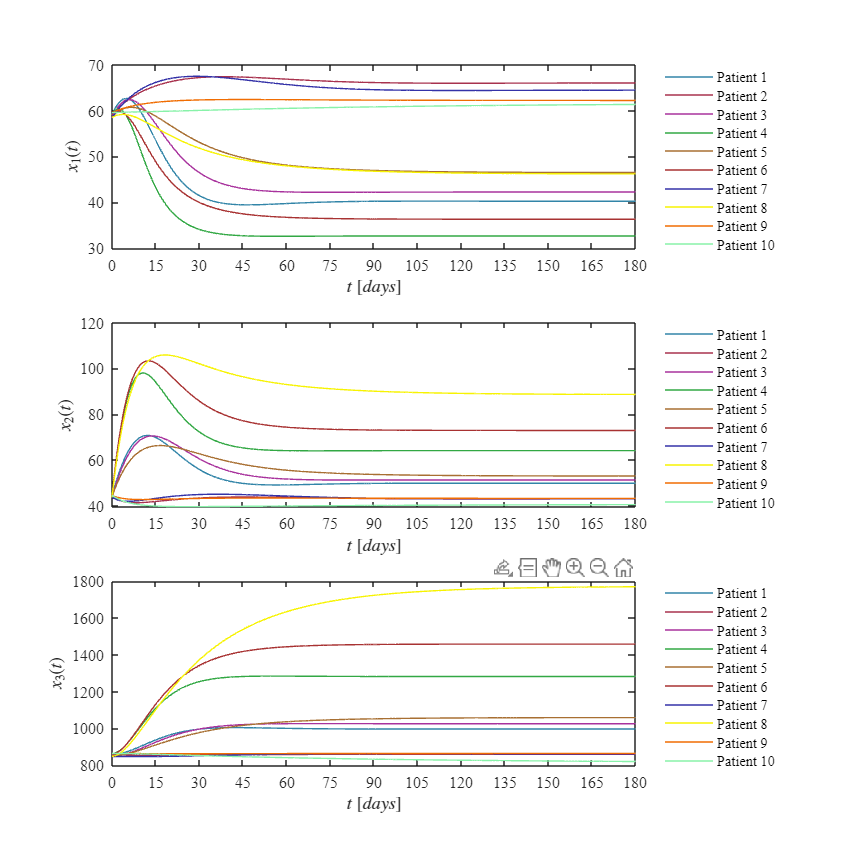

u = zeros(n+1,1); %No hay transfusion 
fig = 1;
    for i = 1:10
    [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
    plotdata(t,x1,x2,x3,fig)
    end

## Caso: Con transfusion sanguinea 

ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


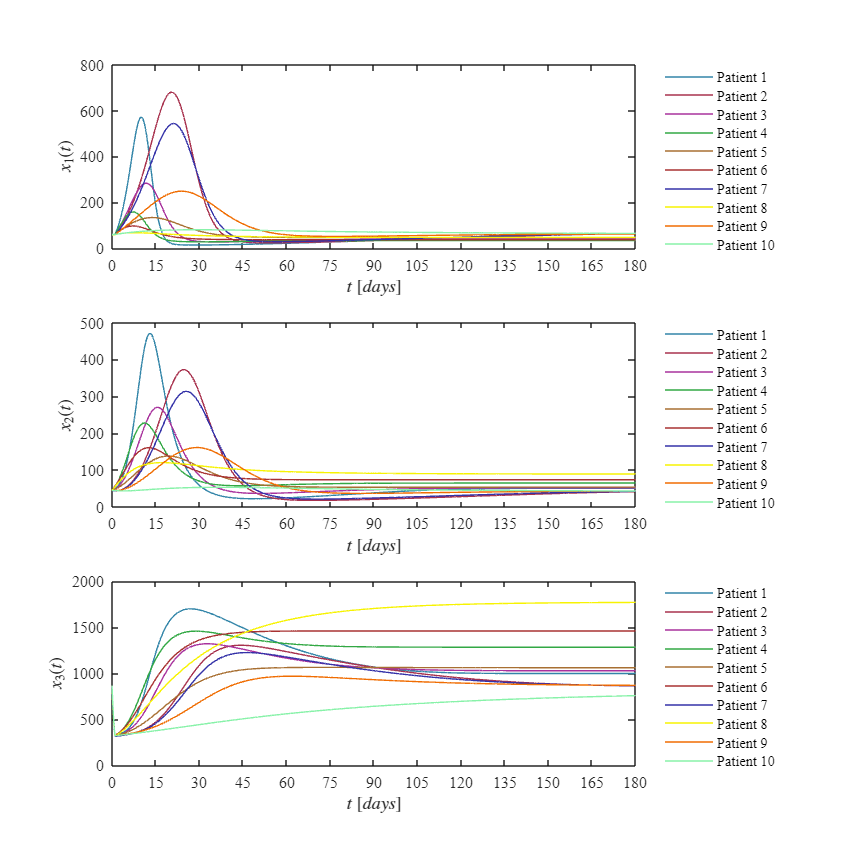

u = zeros(size(t)); 

for k = 1:length(t)
    if t(k) >= 0
        if t(k) <= 1
            u(k) = 1;
        end
    end
end

fig = 2;
for i = 1:10
    [t, x1, x2, x3] = system(x1_0(i), x2_0(i), x3_0(i), beta(i), gamma(i), u, dt, tend);
    plotdata(t, x1, x2, x3, fig)
end

## Funcion: Modelo matematico


$$\dot{x_1 } =\beta \left(x_0 -k_1 x_1 \right)+\frac{\gamma \left(B_{\textrm{ase}} -x_3 \right)\left(1-u\left(t\right)\right)x_1 }{B_{\textrm{ase}} }$$



$$\dot{x_2 } =\beta \left(k_1 x_1 -k_2 x_2 \right)$$



$$\dot{x_3 } =\beta \left(k_2 x_2 -\alpha x_3 \right)-u\left(t\right)x_3$$


function [t,x1,x2,x3] = system(x1_0,x2_0,x3_0,beta,gamma,u,dt,tend)
%Parametros fijos del sistema
Base = 885.43; X0 = 7.3785; k1 = 0.125; k2 = 0.1667; alpha = 0.00833;
t = (0:dt:tend)';
n = round(tend/dt);
x1= zeros(n+1,1); x1(1) = x1_0;
x2= zeros(n+1,1); x2(1) = x2_0;
x3= zeros(n+1,1); x3(1) = x3_0;

    for i = 1:n
    x1(i+1) = x1(i) + (beta*(X0-k1*x1(i))+ gamma*(Base - x3(i))* (1- u(i))* x1(i)/Base)*dt;
    x2(i+1) = x2(i) + (beta*k1*x1(i)- k2*x2(i))*dt;
    x3(i+1) = x3(i) + (beta*(k2*x2(i) - alpha*x3(i))-u(i)*x3(i))*dt;
    end
end

## Funcion: Soluciones en el tiempo 

function plotdata(t,x1,x2,x3,fig)
    set(figure(fig),'Color','w')
    set(gcf,'Units','Centimeters','Position',[1,1,20,20])
    mycolors = [50,133,168;   
                168,50,78;
                168,50,157;
                50,168,68;
                168,111,50;
                168,50,50;
                52,50,168;
                247,243,2;
                240,109,2;
                136,242,169]/255;

    subplot(3,1,1)
    hold on; grid off; box on; colororder(mycolors)
    plot(t,x1)
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
    ylabel('$x_1(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    set(gca,'FontName','Times New Roman','Fontsize',10)
    L= legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5','Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca,'FontName','Times New Roman','FontSize',10)
    
    subplot(3,1,2)
    hold on; grid off; box on; colororder(mycolors)
    plot(t,x2)
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
    ylabel('$x_2(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    set(gca,'Fontname','Times New Roman','Fontsize',10)
    L= legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5','Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca,'FontName','Times New Roman','FontSize',10)
    
    subplot(3,1,3)
    hold on; grid off; box on; colororder(mycolors)
    plot(t,x3)
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
    ylabel('$x_3(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    set(gca,'Fontname','Times New Roman','Fontsize',10)
    L= legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5','Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca,'FontName','Times New Roman','FontSize',10)

    if fig==1
        exportgraphics(gcf,'Caso sin transfusion.pdf','ContentType','vector')
    else fig == 2
        exportgraphics(gcf,'Caso con transfusion.pdf','ContentType','vector')
        end


end